# **Generation of one-dimensional mesh along line**

It returns an one-dimensional linear two-noded mesh along a line:

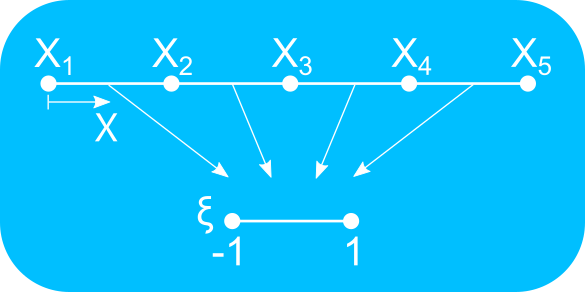

function msh = generateLinearMeshOnLine(X0, XL, numElements)

## **Function Description**

Returns a structure containing the nodes and the elements on a line corresponding to a linear two-noded mesh.

**             Input :**

            X0,XL : The end points of the one-dimensional domain

numElements : Number of nodes in the one-dimensional mesh

**          Output :**

               msh : The one-dimensional mesh using two-noded elements as a structure with the following fields:

                            .nodes : Number of nodes in the one-dimensional mesh

                       .elements : Number of elements in the one-dimensional mesh

## **Function Implementation**

### Input validation

    arguments
        X0 (1, 1) double
        XL (1, 1) double
        numElements (1, 1) double {mustBeInteger, mustBeGreaterThanOrEqual(numElements, 1)}
    end

### Mesh generation

    msh.nodes = linspace(X0, XL, numElements + 1)';
    msh.elements = zeros(numElements, 2);
    for ii = 1:numel(msh.elements(:, 1))
        msh.elements(ii, :) = [ii ii + 1];
    end

end